# MATLAB Companion Script for *Machine Learning* ex6 (Optional)

## Introduction

Coursera's* Machine Learning* was designed to provide you with a greater understanding of machine learning algorithms- what they are, how they work, and where to apply them. You are also shown techniques to improve their performance and to address common issues. As is mentioned in the course, there are many tools available that allow you to use machine learning algorithms *without* having to implement them yourself. This Live Script was created by MathWorks to help *Machine Learning* students explore the data analysis and machine learning tools available in MATLAB.

## FAQ

**Who is this intended for?**

- This script is intended for students using MATLAB Online who have completed ex6 and want to learn more about the corresponding machine learning tools in MATLAB.

**How do I use this script?**

- In the sections that follow, read the information provided about the data analysis and machine learning tools in MATLAB, then run the code in each section and examine the results. You may also be presented with instructions for using a MATLAB machine learning app. This script should be located in the ex6 folder which should be set as your Current Folder in MATLAB Online.

**Can I use the tools in this companion script to complete the programming exercises?**

- No. Most algorithm steps implemented in the programming exercises are handled automatically by MATLAB machine learning functions. Additionally, the results will be similar, but not identical, to those in the programming exercises due to differences in implementation, parameter settings, and randomization.

**Where can I obtain help with this script or report issues?**

- As this script is not part of the original course materials, please direct any questions, comments, or issues to the *MATLAB Help* discussion forum.

# Support Vector Machines

In this Live Script, we will create and train [support vector machine ](https://www.mathworks.com/help/stats/support-vector-machines-for-binary-classification.html)classification models using apps and functions from the [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html). 

## **Files needed for this script:**

- `ex6data1.mat` - Example Dataset 1

- `ex6data2.mat` - Example Dataset 2

- `ex6data3.mat` - Example Dataset 3

- `spamTrain.mat` - Spam training set

- `spamTest.mat` - Spam test set

- emailSample1.txt - Sample email 1

- emailSample2.txt - Sample email 2

- spamSample1.txt - Sample spam 1

- spamSample2.txt - Sample spam 2

- vocab.txt - Vocabulary list

# Train a Linear SVM with the Classification Learner App

In this section we train and export an linear SVM classifier model using the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html).

## **Load dataset 1**

Run the code below to load example dataset 1, which consists of two feature variables in the matrix `X` and the binary response vector `y`. The variables are concatenated into a single data matrix, `data` for use with the Classification Learner App.

clear;
load ex6data1.mat;
data = [X,y];

Follow the steps in the next few sections to train and export an SVM classifier.

**Note: **If you have difficulty reading the instructions below while the app is open in MATLAB Online, export this script to a pdf file which you can then use to display the instructions in a seperate browser tab or window. To export this script, click on the 'Save' button in the 'Live Editor' tab above, then select 'Export to PDF'.

## **Open the app and select the predictor and response variables**

- In the MATLAB Apps tab, select the '**Classification Learner'** from the '**Machine Learning'** section (you may need to expand the menu of available apps).

- Select '**New Session -> From Workspace**' to start a new interactive session.

- Under '**Workspace Variable'**, select '**data**'.

- Under '**Validation**', select '**Cross-Validation**' and use the slider to select 10 folds (see the companion script for ex5 for more information on K-fold cross-validation)

- Click the '**Start Session**' button. 

## **Select and train the model**

- In the model list, the default model is 'Fine Tree'. Expand the model list and select '**Linear SVM**' from the '**Support Vector Machines**' list.

- Select '**Train**' to train the model. Note that the data is automatically normalized before training.

## **Evaluate the model**

After training, there are several options available for evaluating the model's performance. 

- The '**Scatter Plot**' is automatically updated to indicate misclassified objects with an 'x' marker.

- The '**Confusion Matrix**' plot contains the correct and incorrect model predictions by class.

- The '**Current Model**' pane contains a summary of the model as well as the training accuracy, training time, and prediction speed for comparison with other models. 

## **Export the model to the workspace and extract the model variable**

- Select '**Export Model -> Export Model**'.

- Select the default output variable name ('trainedModel') and click '**OK**'.

- Run the code below to extract the classifier model into the variable `linSVMmdl`

linSVMmdl = trainedModel.ClassificationSVM

linSVMmdl =   ClassificationSVM
           PredictorNames: {'column_1'  'column_2'  'column_3'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 51
                    Alpha: [6×1 double]
                     Bias: -0.1924
         KernelParameters: [1×1 struct]
                       Mu: [2.2688 3.1325 0.4118]
                    Sigma: [0.9285 0.7533 0.4971]
           BoxConstraints: [51×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [51×1 logical]
                   Solver: 'SMO'


  Properties, Methods


## **Predict classes and visualize the decision boundary using the **`predict`** function**

As with the other model variables discussed previously in the companion scripts, all of the information about the SVM model is included in the model variable- in this case a [classificationSVM](https://www.mathworks.com/help/stats/classificationsvm.html) model variable. This includes the training data and information, model coefficients, normalization coefficients, etc. The model variable can then be used to predict the class of new feature data using the [`predict`](https://www.mathworks.com/help/stats/compactclassificationsvm.predict.html) function.  Run the code below to predict the class of a random training example and plot the decision boundary using the `decisionBoundary` function (included at the end of this script as a local function) for comparison with your results from ex6. Note that normalization was automatically implemented by the Classification Learner App before training the SVM model, there is no need to normalize feature data before passing it to `predict`, the data will again be normalized automatically before prediction. 

idx = randi(length(y));

Unrecognized function or variable 'y'.

fprintf('Data Point: %d | True class: %d | Predicted class: %d',idx,y(idx),predict(linSVMmdl, X(idx,:)));
decisionBoundary(linSVMmdl,X,y);

# Train a Gaussian Kernel SVM with the Classification Learner App

Next, we'll create, train, and export a *non-linear* classification model using a Gaussian kernel. 

## **Load dataset 2**

Run the code below to clear the previous variables and load dataset 2. The feature and response arrays are again combined into a single matrix, `data`. 

clear;
load ex6data2.mat;
data = [X,y];

## Train a Gaussian kernel model

To fit a Gaussian kernel SVM classifier to dataset 2, repeat the steps in the previous section ***except***: 

- Select the '**Fine Gaussian**' model* instead of **Linear SVM**' from the '**Support Vector Machines**' model list.

*Alternative Gaussian kernels are available, include 'Medium' and 'Coarse', which differ in the value of `KernelScale` model parameter. This parameter is discussed later in this script and its value can be set manually in the Classification Learner App, if desired. 

## **Extract the model and visualize the decision boundary**

Exporting the trained model to the variable `trainedModel`, then run the code below to extract the classifier model into the variable `gaussSVMmdl` and plot the decision boundary. 

gaussSVMmdl = trainedModel.ClassificationSVM

gaussSVMmdl =   ClassificationSVM
           PredictorNames: {'column_1'  'column_2'  'column_3'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 863
                    Alpha: [118×1 double]
                     Bias: 0.1769
         KernelParameters: [1×1 struct]
                       Mu: [0.5034 0.6943 0.5562]
                    Sigma: [0.2550 0.1589 0.4971]
           BoxConstraints: [863×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [863×1 logical]
                   Solver: 'SMO'


  Properties, Methods


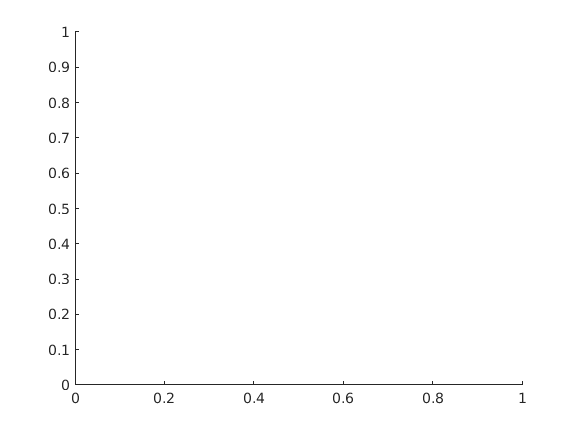

Error using classreg.learning.impl.CompactSVMImpl/score (line 68)
You must pass X as a matrix with 3 columns.

Error in classreg.learning.classif.CompactClassificationSVM/score (line 576)
            f = score(this.Impl,X,true,varargin{:});

Error in 

decisionBoundary(gaussSVMmdl,X,y)

# Fit an SVM model and explore the effect of model parameters using `fitcsvm`

In ex6, you explored the effect of the SVM parameters $C$ and $\sigma$ on the model performance. In this section, we train a cross-validated SVM programmatically using the [`fitcsvm`](https://www.mathworks.com/help/stats/fitcsvm.html) function, where the $C$ and $\sigma$ parameters effectively correspond to the `fitcsvm` options `'BoxConstraint'` and `'KernelScale'` respectively.

## **Load dataset 3**

Run the code below to clear the current model and load dataset 3. (After completing this section, you can repeat the analysis by select one of the first two data sets.)

clear;
dataset = 3;
load(['ex6data' num2str(dataset) '.mat']);

## Train an SVM classifier with custom parameter settings

Select values for the `BoxConstraint` and `KernelScale`, then run the code in this section to train an SVM classifier using [`fitcsvm`](https://www.mathworks.com/help/stats/fitcsvm.html)` to` examine the effect of the parameters on the model. A warning may be displayed for certain parameter choices if the decision boundary is not rendered (when all examples are predicted to have the same class). 

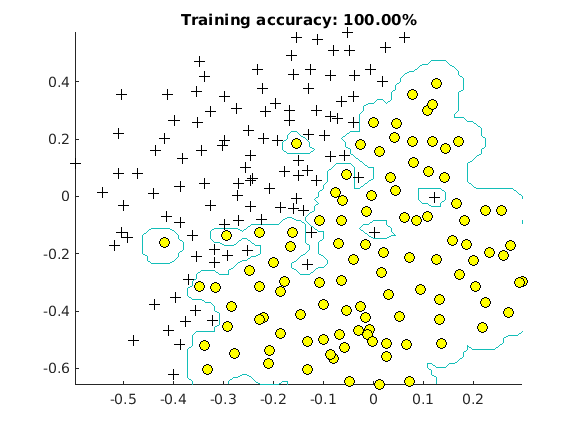

kernelscale = 0.1;
boxconstraint = 1000;
gaussSVMmdl = fitcsvm(X,y,...
                     'BoxConstraint',boxconstraint,...
                     'KernelScale',kernelscale,...
                     'Standardize',true,...
                     'KernelFunction','gaussian');

decisionBoundary(gaussSVMmdl,X,y);
title(sprintf('Training accuracy: %0.2f%%', 100*mean(predict(gaussSVMmdl,X)==y)));

**Note:** The `BoxConstraint` and `KernelScale` parameters are also customizable in the Classification Learner App. After selecting an SVM classification model, click the '**Advanced**' button to change these parameter values. (The `KernelScale` option is not available for linear kernels).  

## Automatically select `BoxConstraint` and `KernelScale` using hyperparameter optimization

In the previous section you likely found several pairs of parameter values that result in good training performance and which are also likely generalize well to new data. This is due to the similar effects these parameters have on the final model. In this section we automatically select `BoxConstraint` and `KernelScale` using hyperparameter optimization. Hyperparameter optimization was discussed previously in the companion script for ex5. Run the code below to create an options structure for K-fold cross-validation and to increase the number of optimization steps to 60. The `fitcsvm` function is then called with `BoxConstraint` and `KernelScale` parameters selected for optimization. (This may take a minute to train). The final model returned by `fitcsvm` corresponds to the one with the optimal hyperparameters*.  

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.49763 |       1.426 |     0.49763 |     0.49763 |    0.0022742 |      0.74043 |


|    2 | Accept |     0.49763 |     0.29513 |     0.49763 |     0.49763 |     0.046235 |    0.0013739 |


|    3 | Accept |     0.49763 |     0.15538 |     0.49763 |     0.49763 |       8.2335 |       400.66 |


|    4 | Best   |    0.080569 |       0.109 |    0.080569 |     0.11207 |       1.0532 |       1.2041 |


|    5 | Accept |    0.080569 |     0.22011 |    0.080569 |    0.080523 |       1.0054 |       1.4258 |


|    6 | Accept |     0.49763 |    0.069034 |    0.080569 |    0.080573 |      0.51463 |     0.012384 |


|    7 | Best   |    0.075829 |    0.059921 |    0.075829 |    0.075846 |       2.3157 |       1.6981 |


|    8 | Accept |       0.109 |    0.058915 |    0.075829 |     0.07585 |       5.8935 |      0.75423 |


|    9 | Best   |    0.066351 |    0.059832 |    0.066351 |    0.066437 |       43.959 |       3.1034 |


|   10 | Accept |    0.075829 |     0.11489 |    0.066351 |      0.0664 |       518.53 |       2.3877 |


|   11 | Accept |    0.080569 |    0.057986 |    0.066351 |    0.066403 |       234.21 |       6.4902 |


|   12 | Accept |    0.080569 |     0.06395 |    0.066351 |    0.066812 |       134.79 |       3.0105 |


|   13 | Accept |    0.085308 |    0.060362 |    0.066351 |    0.070633 |       15.465 |       5.2659 |


|   14 | Accept |    0.080569 |    0.082328 |    0.066351 |    0.071154 |       997.67 |       4.8936 |


|   15 | Accept |    0.066351 |    0.054231 |    0.066351 |    0.067582 |       13.663 |       2.4606 |


|   16 | Accept |    0.080569 |    0.054322 |    0.066351 |    0.072596 |       16.036 |       2.5602 |


|   17 | Accept |    0.090047 |    0.055031 |    0.066351 |    0.071467 |       4.6521 |        2.377 |


|   18 | Accept |     0.07109 |    0.051357 |    0.066351 |     0.07114 |       51.346 |        3.423 |


|   19 | Accept |     0.15166 |    0.060979 |    0.066351 |    0.071217 |       985.42 |      0.44807 |


|   20 | Accept |    0.075829 |    0.052044 |    0.066351 |    0.072258 |       45.593 |       3.2293 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|   21 | Accept |     0.50237 |    0.058912 |    0.066351 |    0.072267 |       47.214 |    0.0010008 |


|   22 | Accept |     0.48815 |     0.05581 |    0.066351 |    0.072301 |       75.787 |     0.018698 |


|   23 | Accept |     0.37441 |    0.057246 |    0.066351 |    0.072202 |       998.66 |       981.33 |


|   24 | Accept |    0.080569 |    0.052226 |    0.066351 |    0.072125 |       990.39 |       94.453 |


|   25 | Accept |    0.085308 |    0.063259 |    0.066351 |    0.072192 |       997.02 |       32.926 |


|   26 | Accept |    0.080569 |    0.058136 |    0.066351 |    0.073081 |       38.791 |       2.2879 |


|   27 | Accept |    0.075829 |    0.052062 |    0.066351 |    0.073358 |       47.584 |       4.0209 |


|   28 | Accept |    0.085308 |     0.17764 |    0.066351 |     0.07338 |       996.67 |       2.2294 |


|   29 | Accept |    0.075829 |    0.051077 |    0.066351 |    0.073357 |       992.66 |       59.017 |


|   30 | Accept |     0.50237 |    0.054417 |    0.066351 |    0.073415 |       2.5776 |    0.0010027 |


|   31 | Accept |     0.34597 |    0.065311 |    0.066351 |    0.073462 |        9.327 |      0.08173 |


|   32 | Accept |    0.099526 |    0.049819 |    0.066351 |    0.073811 |       41.239 |       52.723 |


|   33 | Accept |    0.075829 |    0.050265 |    0.066351 |    0.073869 |       187.49 |       37.736 |


|   34 | Accept |    0.080569 |    0.052097 |    0.066351 |    0.073883 |       74.395 |       20.735 |


|   35 | Accept |     0.07109 |    0.054485 |    0.066351 |     0.07385 |       334.86 |       53.876 |


|   36 | Accept |     0.07109 |    0.054777 |    0.066351 |    0.073796 |       336.26 |        52.56 |


|   37 | Accept |     0.07109 |    0.054451 |    0.066351 |    0.071709 |       349.46 |       54.021 |


|   38 | Accept |    0.075829 |     0.04833 |    0.066351 |    0.072567 |       353.01 |       53.701 |


|   39 | Accept |     0.49763 |    0.057628 |    0.066351 |    0.072579 |       997.79 |    0.0037269 |


|   40 | Accept |     0.46445 |    0.058932 |    0.066351 |     0.07259 |       999.45 |     0.045397 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|   41 | Accept |     0.49763 |    0.057922 |    0.066351 |    0.072603 |       990.93 |    0.0010109 |


|   42 | Accept |     0.50237 |    0.062062 |    0.066351 |    0.072612 |       5.5261 |     0.003829 |


|   43 | Accept |     0.11848 |    0.062177 |    0.066351 |    0.071284 |       217.35 |       333.58 |


|   44 | Accept |     0.11374 |    0.064229 |    0.066351 |    0.072682 |       236.91 |       121.77 |


|   45 | Accept |     0.10427 |    0.057279 |    0.066351 |    0.072834 |       998.99 |       250.73 |


|   46 | Accept |    0.075829 |    0.067352 |    0.066351 |    0.072801 |       14.578 |       19.699 |


|   47 | Accept |    0.080569 |    0.048933 |    0.066351 |    0.072835 |       29.046 |       12.079 |


|   48 | Accept |    0.080569 |    0.049039 |    0.066351 |    0.072789 |       33.852 |       26.249 |


|   49 | Accept |     0.07109 |    0.049054 |    0.066351 |    0.072665 |       436.35 |       46.705 |


|   50 | Accept |    0.090047 |    0.053309 |    0.066351 |    0.072656 |       3.9739 |       14.096 |


|   51 | Accept |    0.075829 |    0.053697 |    0.066351 |    0.073083 |       446.22 |       47.567 |


|   52 | Best   |    0.061611 |    0.058163 |    0.061611 |    0.064917 |       4.4975 |       1.4192 |


|   53 | Accept |    0.080569 |    0.065947 |    0.061611 |     0.07254 |        6.235 |       1.4351 |


|   54 | Accept |     0.07109 |    0.061637 |    0.061611 |    0.070276 |       2.9064 |        1.331 |


|   55 | Accept |     0.07109 |    0.071405 |    0.061611 |    0.070407 |       2.9004 |       1.3492 |


|   56 | Accept |     0.07109 |    0.094262 |    0.061611 |    0.070519 |       3.0196 |       1.3545 |


|   57 | Accept |    0.080569 |     0.11173 |    0.061611 |    0.070537 |       997.84 |       10.889 |


|   58 | Accept |     0.07109 |     0.14207 |    0.061611 |    0.070722 |       249.04 |       1.2544 |


|   59 | Accept |    0.080569 |     0.22891 |    0.061611 |    0.070869 |       343.81 |       1.4551 |


|   60 | Accept |    0.075829 |    0.080498 |    0.061611 |    0.071002 |        64.03 |       1.2796 |


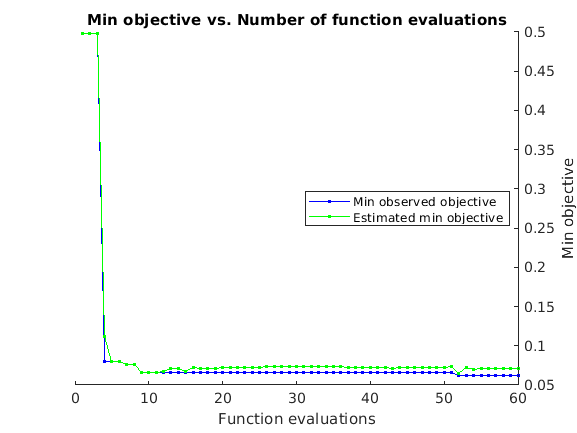

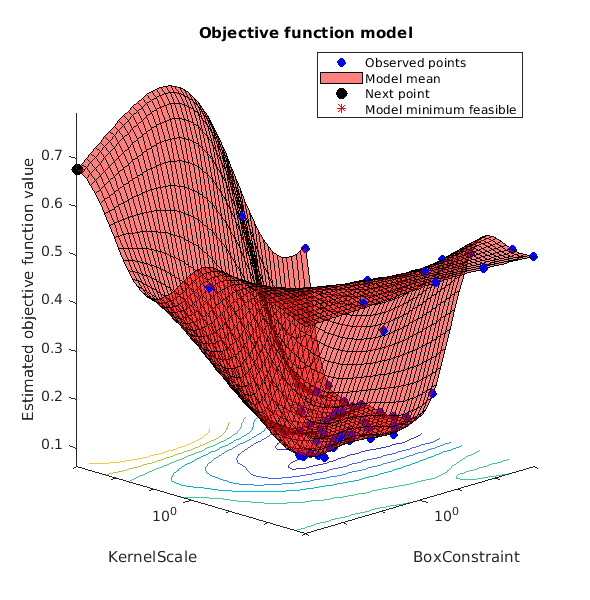


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 60 reached.
Total function evaluations: 60
Total elapsed time: 115.0365 seconds.
Total objective function evaluation time: 5.9274

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       4.4975          1.4192   

Observed objective function value = 0.061611
Estimated objective function value = 0.071805
Function evaluation time = 0.058163

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       3.0196          1.3545   

Estimated objective function value = 0.071002
Estimated function evaluation time = 0.072208



gaussSVMmdl =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 211
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [60×1 double]
                                 Bias: 0.2737
                     KernelParameters: [1×1 struct]
                                   Mu: [-0.1302 -0.0597]
                                Sigma: [0.2005 0.3148]
                       BoxConstraints: [211×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [211×1 logical]
                               Solver: 'SMO'


  Properties, Methods


folds = 5;
opts = struct('kfold',folds,'MaxObjectiveEvaluations',60,'Repartition',true);
gaussSVMmdl = fitcsvm(X,y,...
                      'KernelFunction','gaussian',...
                      'Standardize',true,...
                      'OptimizeHyperparameters',{'KernelScale','BoxConstraint'},...
                      'HyperparameterOptimizationOptions',opts)

***Note:** As there are two parameters being optimized the cost function is visualized *as a surface* over a grid of `BoxConstraint` and `KernelScale` values. Furthermore, the range of parameter combinations resulting in acceptable performance observed in the previous section is seen as the 'trough' in the 'Objective function model' plot. Along this trough are parameter pairs that will provide similar performance as judged by the validation cost. Due to the random nature of validation set selection, your optimal parameter pair may vary along this region upon successive training/parameter optimizations but should still result in comparable performance. 

## **Examine the results**

Run the code below to plot the decision boundary of the optimized SVM classifier. 

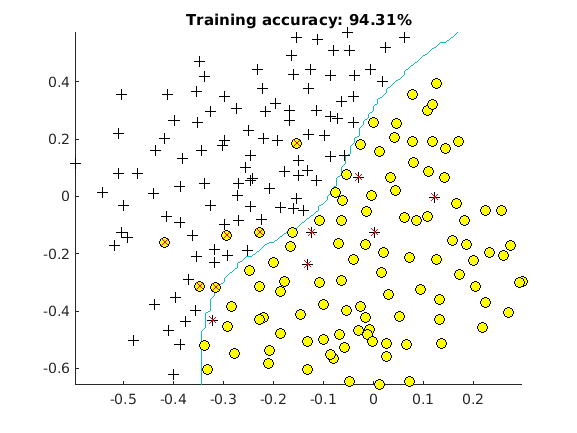

decisionBoundary(gaussSVMmdl,X,y);
title(sprintf('Training accuracy: %0.2f%%', 100*mean(predict(gaussSVMmdl,X)==y)));

# Text Processing and Spam Email Classification

In the second part of ex6, you preprocessed and stemmed text data in the form of email samples, then trained an SVM to classify the samples as spam or not spam. In this section we introduce MATLAB `string` variables and use them to preprocess text data before training a spam classifier.

## MATLAB `string` variables

[`string` arrays](https://www.mathworks.com/help/matlab/characters-and-strings.html) provide a rich set of functionality for processing and analyzing textual data. They are now the preferred text datatype in MATLAB and offer advantages in most cases over character arrays (`char`) and cell arrays of `char` variables. Use the control below to list and obtain descriptions of the functions available for working with `strings`. Note that certain methods also have equivalent operators. For example, '+' and '==' can be used in place of `plus` and `eq`. 

help string.strip

 strip Remove leading and trailing whitespaces
    NEWSTR = strip(STR) removes all consecutive whitespace characters from
    the beginning and the end of STR. Whitespace is defined as any sequence
    of whitespace characters such as spaces, tabs, and newlines.
 
    STR can be a string array, character vector, or cell array of character
    vectors. If STR is a string array or cell array, then strip removes
    leading and trailing whitespace from each element of STR.
 
    NEWSTR = strip(STR,SIDE) removes whitespace characters from the
    specified SIDE. SIDE can be 'left', 'right', or 'both'.  The default
    value of SIDE is 'both'.
 
    NEWSTR = strip(STR,PAD_CHARACTER) removes PAD_CHARACTER from STR.
    PAD_CHARACTER must be exactly one character.
  
    NEWSTR = strip(STR,SIDE,PAD_CHARACTER) removes PAD_CHARACTER from the
    specified SIDE.
  
    Example:
 
        STR = [

## Load text data

Run the code below to load a sample email into a character vector `contents`. You can return and select a different sample to see the results of the preprocessing operations in the next section.

clear;
file = 'emailSample1.txt';
contents = fileread(file);

## Preprocess text using `string` methods and functions

In this section, we will convert the email contents to a string and preprocess the email using the same steps as in the ex6 function `processEmail.` If you are curious, you can remove the semicolon after one or more commands to examine the effects of the processing steps below. These steps have been collected into the local function `preprocess` at the end of this script which will be used in the remainder of this Live Script.

- Convert `contents` to a `string`

processed = string(contents)

processed =     "> Anyone knows how much it costs to host a web portal ?
     >
     Well, it depends on how many visitors you're expecting.
     This can be anywhere from less than 10 bucks a month to a couple of $100. 
     You should checkout http://www.rackspace.com/ or perhaps Amazon EC2 
     if youre running something big..
     
     To unsubscribe yourself from this mailing list, send an email to:
     groupname-unsubscribe@egroups.com
     
     "


- Lower-case the string using `lower`.

processed  = lower(processed)

processed =     "> anyone knows how much it costs to host a web portal ?
     >
     well, it depends on how many visitors you're expecting.
     this can be anywhere from less than 10 bucks a month to a couple of $100. 
     you should checkout http://www.rackspace.com/ or perhaps amazon ec2 
     if youre running something big..
     
     to unsubscribe yourself from this mailing list, send an email to:
     groupname-unsubscribe@egroups.com
     
     "


- Strip HTML tags using `eraseBetween`

processed  = eraseBetween(processed,'<','>','Boundaries','inclusive')

processed =     "> anyone knows how much it costs to host a web portal ?
     >
     well, it depends on how many visitors you're expecting.
     this can be anywhere from less than 10 bucks a month to a couple of $100. 
     you should checkout http://www.rackspace.com/ or perhaps amazon ec2 
     if youre running something big..
     
     to unsubscribe yourself from this mailing list, send an email to:
     groupname-unsubscribe@egroups.com
     
     "


- Replace dollar signs with 'dollar'

processed = replace(processed,"$","dollar")

processed =     "> anyone knows how much it costs to host a web portal ?
     >
     well, it depends on how many visitors you're expecting.
     this can be anywhere from less than 10 bucks a month to a couple of dollar100. 
     you should checkout http://www.rackspace.com/ or perhaps amazon ec2 
     if youre running something big..
     
     to unsubscribe yourself from this mailing list, send an email to:
     groupname-unsubscribe@egroups.com
     
     "


- Split the email on whitespace into individual tokens (`contents` will become a `string` *array*)

processed = split(processed)

processed = 65×1 string array
    ">"
    "anyone"
    "knows"
    "how"
    "much"
    "it"
    "costs"
    "to"
    "host"
    "a"
    "web"
    "portal"
    "?"
    ">"
    "well,"
    "it"
    "depends"
    "on"
    "how"
    "many"
    "visitors"
    "you're"
    "expecting."
    "this"
    "can"
    "be"
    "anywhere"
    "from"
    "less"
    "than"


- Normalize URLs using `contains` and logical indexing

processed(startsWith(processed,["http://","https://"])) =  "httpaddr"

processed = 65×1 string array
    ">"
    "anyone"
    "knows"
    "how"
    "much"
    "it"
    "costs"
    "to"
    "host"
    "a"
    "web"
    "portal"
    "?"
    ">"
    "well,"
    "it"
    "depends"
    "on"
    "how"
    "many"
    "visitors"
    "you're"
    "expecting."
    "this"
    "can"
    "be"
    "anywhere"
    "from"
    "less"
    "than"


- Normalize email addresses and numbers, and remove punctuation using [`regexprep`](https://www.mathworks.com/help/matlab/ref/regexprep.html). 

processed = regexprep(processed,'.+@.+',"emailaddr") 

processed = 65×1 string array
    ">"
    "anyone"
    "knows"
    "how"
    "much"
    "it"
    "costs"
    "to"
    "host"
    "a"
    "web"
    "portal"
    "?"
    ">"
    "well,"
    "it"
    "depends"
    "on"
    "how"
    "many"
    "visitors"
    "you're"
    "expecting."
    "this"
    "can"
    "be"
    "anywhere"
    "from"
    "less"
    "than"


processed = regexprep(processed,'[0-9]+',"number")

processed = 65×1 string array
    ">"
    "anyone"
    "knows"
    "how"
    "much"
    "it"
    "costs"
    "to"
    "host"
    "a"
    "web"
    "portal"
    "?"
    ">"
    "well,"
    "it"
    "depends"
    "on"
    "how"
    "many"
    "visitors"
    "you're"
    "expecting."
    "this"
    "can"
    "be"
    "anywhere"
    "from"
    "less"
    "than"


processed = regexprep(processed,'[^a-zA-Z0-9]',"")

processed = 65×1 string array
    ""
    "anyone"
    "knows"
    "how"
    "much"
    "it"
    "costs"
    "to"
    "host"
    "a"
    "web"
    "portal"
    ""
    ""
    "well"
    "it"
    "depends"
    "on"
    "how"
    "many"
    "visitors"
    "youre"
    "expecting"
    "this"
    "can"
    "be"
    "anywhere"
    "from"
    "less"
    "than"


- Remove empty or single character words using `strlength`

processed(strlength(processed)<=1) = []

processed = 58×1 string array
    "anyone"
    "knows"
    "how"
    "much"
    "it"
    "costs"
    "to"
    "host"
    "web"
    "portal"
    "well"
    "it"
    "depends"
    "on"
    "how"
    "many"
    "visitors"
    "youre"
    "expecting"
    "this"
    "can"
    "be"
    "anywhere"
    "from"
    "less"
    "than"
    "number"
    "bucks"
    "month"
    "to"


## Stem the words in the string array

Run the code below to stem the words using `porterStemmer.m`  (included with ex6). Since `porterStemmer` was created for character arrays, we'll convert the elements of `contents` to character vectors before passing them to `porterStemmer`, then convert the output back into a `string`. 

processed = arrayfun(@(str)string(porterStemmer(char(str))),processed)

processed = 58×1 string array
    "anyon"
    "know"
    "how"
    "much"
    "it"
    "cost"
    "to"
    "host"
    "web"
    "portal"
    "well"
    "it"
    "depend"
    "on"
    "how"
    "mani"
    "visitor"
    "your"
    "expect"
    "thi"
    "can"
    "be"
    "anywher"
    "from"
    "less"
    "than"
    "number"
    "buck"
    "month"
    "to"


## Import the vocabulary list

The next step is to load the vocabulary words in vocab.txt. Since the file contains the (unneeded) word indices as well as the word list, we'll import the data into a `table` usng `readtable`, then select only the words by extracting the second column and converting it into a `string` array.

vocab = readtable('vocab.txt');
vocab = string(vocab{:,2});      

## Map the string array values to the vocabulary list

Run the code below to create a binary vector, `features` where `features(i)` equals `1` if `vocab(i)` appears in `processed` and 0 otherwise. The vocabulary list is then displayed alongside the feature vector in a `table`. To see what vocabulary words are in the email, hover the cursor over '`features`', click down arrow when it appears, then enter '1' for both the largest and smallest value to select between (or sort from largest to smallest). You should see the 48 words from the dictionary that were in found in the first spam email sample.

features = double(ismember(vocab,processed));
table(vocab,features)

ans = 1899×2 table
      vocab      features
    _________    ________

    "aa"            0    
    "ab"            0    
    "abil"          0    
    "abl"           0    
    "about"         0    
    "abov"          0    
    "absolut"       0    
    "abus"          0    
    "ac"            0    
    "accept"        0    
    "access"        0    
    "accord"        0    
    "account"       0    
    "achiev"        0    
    "acquir"        0    
    "across"        0    


If desired, you can load and process a different email to see processed result and the resulting feature vector (there is no need to re-import the vocabulary list.

## Train an SVM for spam classification using `fitclinear`

In this section we train an SVM classifier model for spam detection using the `fitclinear` function. As there are a large number of variables (1,899), the `fitclinear` function will offer improved performance over `fitcsvm`. (As has been mentioned in previous companion scripts, `fitrlinear` and `fitclinear` are more efficient when training models with a large number of variables). Run the code below to load the email training set in `spamTrain.mat` which contains a feature matrix `X` and response vector `y`. The `fitclinear` function is then called to train an SVM model by setting the `'Learner'` option to `'svm'`. We will also add regularization and cross-validate the model using hold-out validation (since there is a large amount of training data in this particular example) and then obtain the optimal regularization strength using hyperparameter optimization. Lastly we will load the test set and compute the training and test accuracies using the optimized classifier. 

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |    0.033333 |     0.98282 |    0.033333 |    0.033333 |   3.2614e-08 |


|    2 | Accept |    0.076667 |     0.53209 |    0.033333 |    0.035614 |        1.129 |


|    3 | Best   |    0.031667 |     0.24654 |    0.031667 |    0.031669 |   4.9461e-05 |


|    4 | Best   |    0.023333 |     0.28022 |    0.023333 |    0.023381 |    0.0042232 |


|    5 | Best   |      0.0225 |     0.49634 |      0.0225 |    0.022499 |    0.0011918 |


|    6 | Accept |       0.035 |     0.21418 |      0.0225 |    0.022496 |   9.4189e-07 |


|    7 | Accept |    0.034167 |     0.19504 |      0.0225 |    0.022496 |   2.5111e-09 |


|    8 | Accept |       0.025 |     0.29308 |      0.0225 |    0.023307 |    0.0019727 |


|    9 | Accept |    0.024167 |     0.22235 |      0.0225 |    0.023476 |    0.0011754 |


|   10 | Accept |    0.023333 |     0.19924 |      0.0225 |    0.023439 |    0.0018427 |


|   11 | Accept |     0.31917 |     0.25063 |      0.0225 |    0.023429 |        24.86 |


|   12 | Accept |       0.035 |     0.22089 |      0.0225 |    0.023495 |     0.077828 |


|   13 | Accept |    0.025833 |      0.1517 |      0.0225 |    0.023717 |   0.00030327 |


|   14 | Best   |        0.02 |     0.20105 |        0.02 |     0.02038 |    0.0087391 |


|   15 | Accept |    0.020833 |     0.19878 |        0.02 |    0.020486 |     0.013136 |


|   16 | Accept |        0.03 |     0.17535 |        0.02 |    0.020529 |   6.2775e-06 |


|   17 | Best   |    0.019167 |     0.18301 |    0.019167 |    0.019973 |     0.010222 |


|   18 | Accept |    0.019167 |     0.21307 |    0.019167 |    0.019744 |     0.010155 |


|   19 | Accept |    0.019167 |     0.18928 |    0.019167 |    0.019607 |     0.010044 |


|   20 | Accept |    0.033333 |     0.18116 |    0.019167 |    0.019629 |   1.5788e-07 |


|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |    0.030833 |     0.16139 |    0.019167 |    0.019641 |    7.366e-09 |


|   22 | Accept |    0.045833 |     0.28047 |    0.019167 |    0.019662 |       0.3051 |


|   23 | Accept |      0.0325 |     0.16157 |    0.019167 |    0.019669 |   1.6855e-05 |


|   24 | Accept |     0.31833 |     0.41295 |    0.019167 |    0.019347 |       4.9811 |


|   25 | Accept |    0.028333 |     0.15972 |    0.019167 |    0.019353 |   0.00013291 |


|   26 | Accept |      0.0325 |     0.16125 |    0.019167 |    0.019358 |   2.4813e-06 |


|   27 | Accept |    0.025833 |     0.19672 |    0.019167 |    0.019374 |     0.031501 |


|   28 | Accept |    0.031667 |     0.17686 |    0.019167 |    0.019377 |   3.6066e-07 |


|   29 | Accept |    0.024167 |     0.15922 |    0.019167 |    0.019381 |   0.00059913 |


|   30 | Accept |    0.020833 |     0.18487 |    0.019167 |    0.019663 |    0.0094907 |


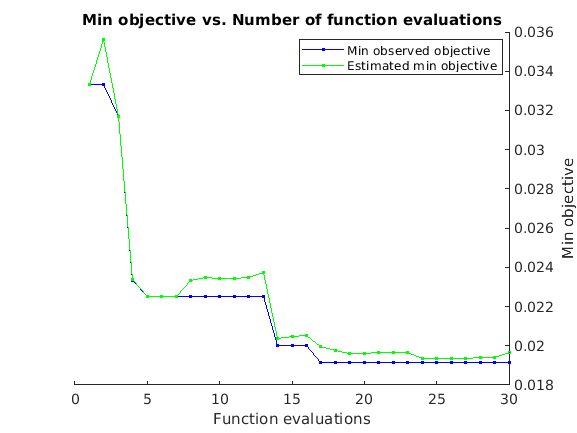

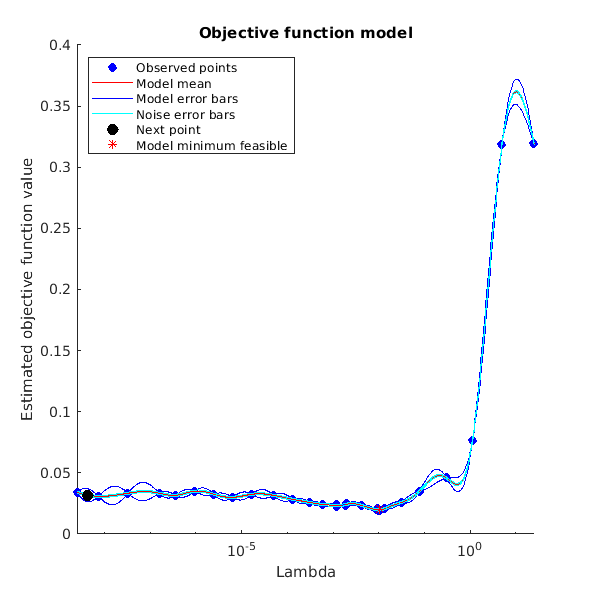


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 70.1078 seconds.
Total objective function evaluation time: 7.6818

Best observed feasible point:
     Lambda 
    ________

    0.010222

Observed objective function value = 0.019167
Estimated objective function value = 0.019661
Function evaluation time = 0.18301

Best estimated feasible point (according to models):
     Lambda 
    ________

    0.010044

Estimated objective function value = 0.019663
Estimated function evaluation time = 0.19867



linSVMmdl =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'none'
              Beta: [1899×1 double]
              Bias: -0.0309
            Lambda: 0.0100
           Learner: 'svm'


  Properties, Methods


load spamTrain.mat;
opts = struct('Holdout',0.3);
linSVMmdl = fitclinear(X,y,'Learner','svm','Regularization','ridge','OptimizeHyperparameters',{'lambda'},'HyperparameterOptimizationOptions',opts)

load('spamTest.mat');
fprintf('Training Accuracy: %f | Test Accuracy: %f\n',...
        mean(predict(linSVMmdl,X)==y)*100,...
        mean(predict(linSVMmdl,Xtest)==ytest)*100);

Training Accuracy: 99.300000 | Test Accuracy: 98.900000


## List the top predictors for spam

As in ex6, we print out the top predictor words as given by their score (model coefficient). The model coefficients are found in the `Beta` model property of a `classificationLinear` variable, which we combine with the vocabulary words into a `table` before sorting. Compare with your results from ex6:

% Sort the weights and obtain the vocabulary list
tbl = table(vocab,linSVMmdl.Beta,'VariableNames',{'Word','Score'})

tbl = 1899×2 table
      Word         Score   
    _________    __________

    "aa"          0.0076679
    "ab"          0.0083176
    "abil"         0.011349
    "abl"         -0.041939
    "about"       -0.073287
    "abov"         0.033553
    "absolut"       0.10022
    "abus"        -0.043691
    "ac"         -0.0019671
    "accept"      -0.015759
    "access"       0.093217
    "accord"      -0.028862
    "account"      0.028092
    "achiev"     -0.0039861
    "acquir"      -0.013221
    "across"       0.029864


tbl = sortrows(tbl,'Score','descend')

tbl = 1899×2 table
       Word         Score 
    ___________    _______

    "click"         0.4256
    "remov"        0.35879
    "basenumb"     0.32952
    "our"          0.30315
    "guarante"     0.28813
    "visit"        0.24456
    "pleas"         0.2411
    "here"         0.22973
    "you"          0.21783
    "free"         0.20364
    "dollar"       0.19812
    "most"         0.19336
    "nbsp"         0.18806
    "hour"         0.18608
    "will"         0.18274
    "multipart"    0.17738


## Classify your own email 

The code below has been set up for you to use your trained model to classify email samples using the trained SVM model and the local function `preprocess`. Just add your own email text file to the Current Folder, add the file name (e.g. 'myemail.txt') to the code below, and select 'yourEmail' using the dropdown menu. Alternatively, you can select and classify the samples included with ex6.

yourEmail = '';
eml = 'spamSample2.txt';
processed = preprocess(eml);
features = ismember(vocab,processed);
if predict(linSVMmdl,double(features)')
    disp('This email is probably spam.')
else
    disp('This email is probably not spam.')
end

This email is probably spam.


# Local Functions

## `decisionBoundary`

The `decisionBoundary` function plots the positive (y = 1) and negative examples of a given dataset provided as an input feature matrix `X` and response vector `y`. The decision boundary for the classifier model `mdl` is also plotted using the `contour` function. Any misclassified points are plotted as red x's.

function decisionBoundary(mdl,X,y)
    figure; hold on;
    x1 = linspace(min(X(:,1)),max(X(:,1)));
    x2 = linspace(min(X(:,2)),max(X(:,2)));
    [Xgrid,Ygrid] = meshgrid(x1,x2);
    Z = reshape(predict(mdl,[Xgrid(:),Ygrid(:)]), size(Xgrid));
    contour(Xgrid,Ygrid,Z,'Levels',1); 
    plot(X(y==1,1),X(y==1,2),'k+','MarkerSize',7);
    plot(X(~y,1),X(~y,2),'ko','MarkerFaceColor','y','MarkerSize',7); 
    misclassidx = y~=predict(mdl,X);
    plot(X(misclassidx,1),X(misclassidx,2),'rx')
    hold off;
end

## `preprocess`

`preprocess` is executes the steps for preprocessing emails used in the Live Script above.

function contents = preprocess(file)
    contents = string(fileread(file));
    contents  = lower(contents);
    contents  = eraseBetween(contents,'<','>','Boundaries','inclusive');
    contents = replace(contents,"$","dollar ");
    contents = split(contents);
    contents(startsWith(contents,["http://","https://"])) =  "httpaddr";
    contents = regexprep(contents,'.+@.+',"emailaddr"); 
    contents = regexprep(contents,'[0-9]+',"number");
    contents = regexprep(contents,'[^a-zA-Z0-9]',"");
    contents(strlength(contents)<=1) = [];
    contents = arrayfun(@(str)string(porterStemmer(char(str))),contents);
end